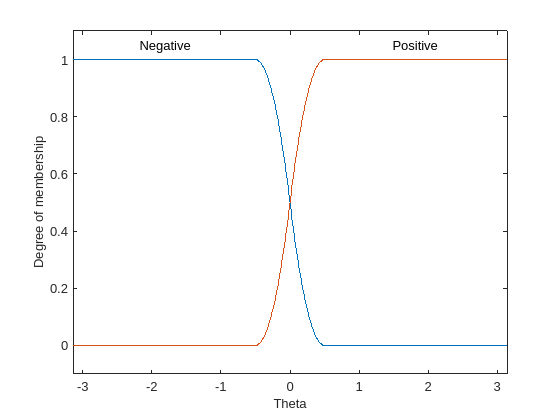

% Cart/Pole Fuzzy Inference System

cartpole3FIS = mamfis(...
    'NumInputs',2,'NumInputMFs',2,...
    'NumOutputs',1,'NumOutputMFs',4,...
    'AddRule','none');

%Inputs
cartpole3FIS.Inputs(1).Name = 'Theta';
cartpole3FIS.Inputs(1).Range = [-pi pi];
cartpole3FIS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cartpole3FIS.Inputs(1).MembershipFunctions(1).Type = 'zmf';
cartpole3FIS.Inputs(1).MembershipFunctions(1).Parameters = [-0.5 0.5];
cartpole3FIS.Inputs(1).MembershipFunctions(2).Name = 'Positive';
cartpole3FIS.Inputs(1).MembershipFunctions(2).Type = 'smf';
cartpole3FIS.Inputs(1).MembershipFunctions(2).Parameters = [-0.5 0.5];

cartpole3FIS.Inputs(2).Name = 'Theta_dot';
cartpole3FIS.Inputs(2).Range = [-5 5];
cartpole3FIS.Inputs(2).MembershipFunctions(1).Name = 'Negative';
cartpole3FIS.Inputs(2).MembershipFunctions(1).Type = 'zmf';
cartpole3FIS.Inputs(2).MembershipFunctions(1).Parameters = [-5 5];
cartpole3FIS.Inputs(2).MembershipFunctions(2).Name = 'Positive';
cartpole3FIS.Inputs(2).MembershipFunctions(2).Type = 'smf';
cartpole3FIS.Inputs(2).MembershipFunctions(2).Parameters = [-5 5];

cartpole3FIS.Inputs(3).Name = 'Cart_position';
cartpole3FIS.Inputs(3).Range = [-2 2];
cartpole3FIS.Inputs(3).MembershipFunctions(1).Name = 'Negative';
cartpole3FIS.Inputs(3).MembershipFunctions(1).Type = 'zmf';
cartpole3FIS.Inputs(3).MembershipFunctions(1).Parameters = [-1 1];
cartpole3FIS.Inputs(3).MembershipFunctions(2).Name = 'Positive';
cartpole3FIS.Inputs(3).MembershipFunctions(2).Type = 'smf';
cartpole3FIS.Inputs(3).MembershipFunctions(2).Parameters = [-1 1];

cartpole3FIS.Inputs(4).Name = 'Cart_velocity';
cartpole3FIS.Inputs(4).Range = [-5 5];
cartpole3FIS.Inputs(4).MembershipFunctions(1).Name = 'Negative';
cartpole3FIS.Inputs(4).MembershipFunctions(1).Type = 'zmf';
cartpole3FIS.Inputs(4).MembershipFunctions(1).Parameters = [-5 5];
cartpole3FIS.Inputs(4).MembershipFunctions(2).Name = 'Positive';
cartpole3FIS.Inputs(4).MembershipFunctions(2).Type = 'smf';
cartpole3FIS.Inputs(4).MembershipFunctions(2).Parameters = [-5 5];

plotmf(cartpole3FIS,'input',1,1000);

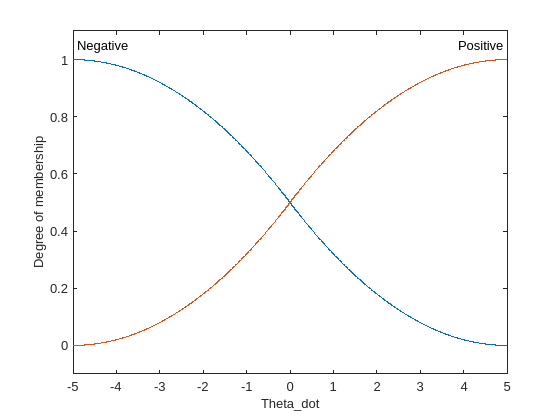

plotmf(cartpole3FIS,'input',2,1000);

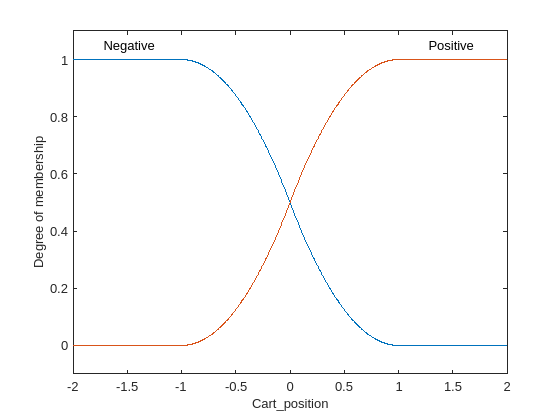

plotmf(cartpole3FIS,'input',3,1000);

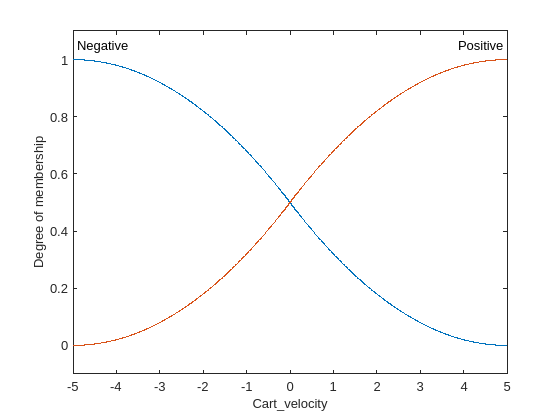

plotmf(cartpole3FIS,'input',4,1000);

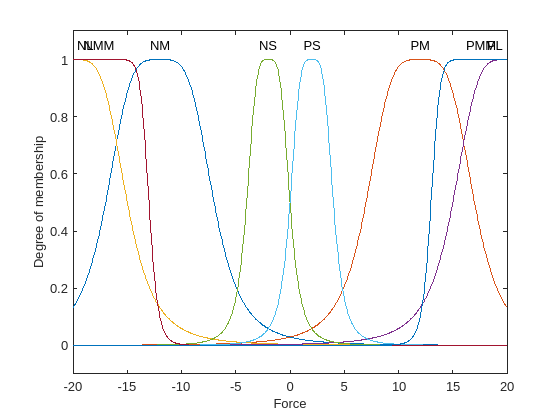


%Outputs
cartpole3FIS.Outputs(1).Name = 'Force';
cartpole3FIS.Outputs(1).Range = [-20 20];

cartpole3FIS.Outputs(1).MembershipFunctions(1).Name = 'NM';%Negative Medium
cartpole3FIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf';
cartpole3FIS.Outputs(1).MembershipFunctions(1).Parameters = [5 2 -12];
cartpole3FIS.Outputs(1).MembershipFunctions(2).Name = 'PM';%Positive Medium
cartpole3FIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf';
cartpole3FIS.Outputs(1).MembershipFunctions(2).Parameters = [5 2 12];

cartpole3FIS.Outputs(1).MembershipFunctions(3).Name = 'NL';%Negative Large
cartpole3FIS.Outputs(1).MembershipFunctions(3).Type = 'gbellmf';
cartpole3FIS.Outputs(1).MembershipFunctions(3).Parameters = [5 2 -20];
cartpole3FIS.Outputs(1).MembershipFunctions(4).Name = 'PL';%Positive Large
cartpole3FIS.Outputs(1).MembershipFunctions(4).Type = 'gbellmf';
cartpole3FIS.Outputs(1).MembershipFunctions(4).Parameters = [5 2 20];

cartpole3FIS.Outputs(1).MembershipFunctions(5).Name = 'NS';%Negative Small
cartpole3FIS.Outputs(1).MembershipFunctions(5).Type = 'gbellmf';
cartpole3FIS.Outputs(1).MembershipFunctions(5).Parameters = [2 2 -2];
cartpole3FIS.Outputs(1).MembershipFunctions(6).Name = 'PS';%Positive Small
cartpole3FIS.Outputs(1).MembershipFunctions(6).Type = 'gbellmf';
cartpole3FIS.Outputs(1).MembershipFunctions(6).Parameters = [2 2 2];

cartpole3FIS.Outputs(1).MembershipFunctions(7).Name = 'NMM';%Negative Medium-LARGE
cartpole3FIS.Outputs(1).MembershipFunctions(7).Type = 'gbellmf';
cartpole3FIS.Outputs(1).MembershipFunctions(7).Parameters = [5 6 -18];
cartpole3FIS.Outputs(1).MembershipFunctions(8).Name = 'PMM';%Positive Medium-LARGE
cartpole3FIS.Outputs(1).MembershipFunctions(8).Type = 'gbellmf';
cartpole3FIS.Outputs(1).MembershipFunctions(8).Parameters = [5 6 18];


plotmf(cartpole3FIS,'output',1,1000);

%Specify Rules
rules = [...
    "If Theta is Negative then Force is NM";...
    "If Theta is Positive then Force is PM";...
    "If Theta_dot is Negative then Force is NL";...
    "If Theta_dot is Positive then Force is PL";...
    "If Cart_position is Negative then Force is PS";...
    "If Cart_position is Positive then Force is NS";...
    "If Cart_velocity is Negative then Force is NMM";...
    "If Cart_velocity is Positive then Force is PMM"];

cartpole3FIS = addRule(cartpole3FIS,rules);